maskRegionsEllipseFit_subCell

Shuai Yang 2021.07.15

% close all
mask = mask1 ;
L = bwlabel(mask);
% s = regionprops(mask, ...
%     'MajorAxisLength','MinorAxisLength', ...
%     'Orientation','PixelIdxList','Centroid','Area');
s = regionprops(mask, 'Area');
mask_ell = false(size(mask));
% s_Ells = struct([]);
tic;
for iCell = 1:numel(s)
    Lcell= +(L == iCell); % + converts logical to double
    Lcell(Lcell == 1)= iCell;
    % disp(num2str(iCell));
    % extract subimages
    [fx, fy] = find(Lcell);
    extra= 8;
    xmin = max(min(fx) - extra, 1);
    xmax = min(max(fx) + extra, size(Lcell,1));
    ymin = max(min(fy) - extra, 1);
    ymax = min(max(fy) + extra, size(Lcell,2));
    subcell = Lcell(xmin:xmax, ymin:ymax);
    
    s_subcell = regionprops(logical(subcell),'MajorAxisLength',...
        'MinorAxisLength', 'Orientation','PixelIdxList','Centroid');
    
    subCell_Ell = false(size(subcell));% each cell ellipse
    
    % ellipse fitting
    angle = s_subcell.Orientation; % 角度
    angle = angle/180*pi;
    r = 0:0.01:2*pi; % 转一圈
    
    a = s_subcell.MajorAxisLength/2;%semi_MajorAxis
    b = s_subcell.MinorAxisLength/2;%semi_minorAxis
    p = [(a*cos(r))' (b*sin(r))']; % 未旋转
    alpha = [cos(angle) -sin(angle)
        sin(angle) cos(angle)];
    p1 = p*alpha; % 旋转后
    p1(:,1) =  p1(:,1) + s_subcell.Centroid(1);
    p1(:,2) =  p1(:,2) + s_subcell.Centroid(2);
    xIdx = round(p1(:,1));
    yIdx = round(p1(:,2));
    
    % 如果超出索引 说明细菌处于边缘 不要
    if max(xIdx) > size(subcell,2) || max(yIdx) > size(subcell,1)
        %         mask_ell(xmin:xmax, ymin:ymax) = ...
        %             or(mask_ell(xmin:xmax, ymin:ymax),subCell_Ell);
        continue
    else
        ind = sub2ind(size(subcell),yIdx(:),xIdx(:));
    end
    
    
    subCell_Ell(ind) = true;
    subCell_EllMask = imfill(subCell_Ell,'holes');
    
    s_subCellEll = regionprops(subCell_EllMask, 'Area');
    
%     s_Ells(iCell).Area = s_subCellEll.Area;
    
    ellIn = and(subCell_EllMask,subcell);
    %椭圆内cell region 面积占比
    ellOut = and(~subCell_EllMask,subcell);
    %椭圆外cell region面积占比
    
    %     s_Ells(iCell).ellInPixels = sum(ellIn(:));
    %     s_Ells(iCell).ellOutPixels = sum(ellOut(:));
    
    %     s(iCell).ellPerimeter = s_subCellEll.Perimeter;
    s(iCell).ellArea = s_subCellEll.Area;
    s(iCell).ellInPixels = sum(ellIn(:));
    s(iCell).ellOutPixels = sum(ellOut(:));
    s(iCell).ellInPixelsProportion = s(iCell).ellInPixels/s(iCell).ellArea;
    
    mask_ell(xmin:xmax, ymin:ymax) = or(mask_ell(xmin:xmax, ymin:ymax),subCell_Ell);
    
end
toc;

历时 11.438713 秒。


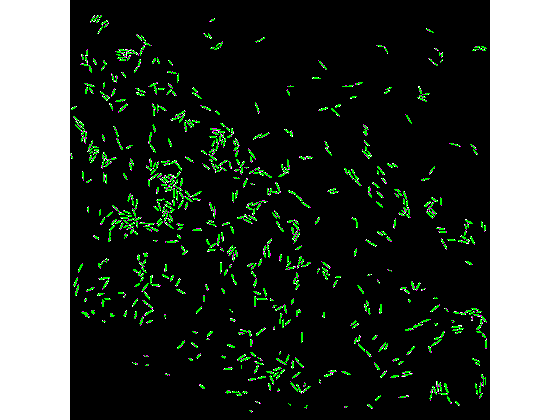

figure,imshowpair(mask,mask_ell)

% ell = patch(p1(:,1),p1(:,2),[255 225 225]/255,'EdgeColor',[1 0 0]);

% 椭圆内细菌区域的面积/椭圆的面积
fwrong = find([s.ellInPixelsProportion] < 0.7);
wrongbw = ismember(L, fwrong);
goodones = setdiff(1:max(max(L)), fwrong);
goodbw = ismember(L, goodones);%没有fwrong剩下的bw图像

% [mergedImage] = showSegMergeOriginalImage(image2,wrongbw)
% [mergedImage] = showSegMergeOriginalImage(image2,goodbw);